# Data quality inspection & handling of issues

The purpose of this tutorial is to demonstrate some tools that can take care of issues.

First, let's load a dataset. The imported and processed dataset from other tutorials will do fine for this tutorial.

## What are we dealing with?

clearvars
close all force
cd(fileparts(matlab.desktop.editor.getActiveFilename))
tbx=drEEMtoolbox;
load("tutorial_01_processed.mat")
disp(samples)

  drEEMdataset with properties:

            history: [11×1 drEEMhistory]
                  X: [32×182×43 double]
                abs: [32×73 double]
        suppSpectra: []
           filelist: {32×1 cell}
                  i: [32×1 double]
                 Ex: [43×1 double]
                 Em: [182×1 double]
                nEx: 43
                nEm: 182
            absWave: [73×1 double]
    suppSpectraAxis: [0×1 double]
            nSample: 32
             models: [0×1 drEEMmodel]
           metadata: [32×15 table]
    opticalMetadata: [0×0 table]
              split: [0×0 drEEMdataset]
             status: [1×1 drEEMstatus]
           userdata: []
     instrumentInfo: [0×0 struct]
    measurementInfo: [0×0 struct]



Let's look at the status of this dataset

disp(samples.status)

  drEEMstatus with properties:

    spectralCorrection: 'applied by instrument software'
         IFEcorrection: "applied by toolbox"
      blankSubtraction: "applied by toolbox"
     signalCalibration: "applied by toolbox (RU)"
      scatterTreatment: "applied by toolbox"
         signalScaling: 'original scale'
        absorbanceUnit: 'absorbance per cm'



You can see that all corrections and processing steps have been completed. If you want to follow what's been done, take a look with `viewhistory` (GUI) or `displayhistory` (console output).

tbx.displayhistory(samples)

    #         Function                              User comment                                                                                                                                                                                                                                                                                              Function message                                                                                                                                                                                                                                                                     
    __    _________________    ______________________________________________________    ____________________________________________________________________________________________________________________________________________________________

That should give you an overview over the dataset.

## Getting an overview

For this dataset, all processing has already taken place. This includes scatter treatment. But how does the data generally look? Take a look with `viewabsorbance` and `vieweems`.

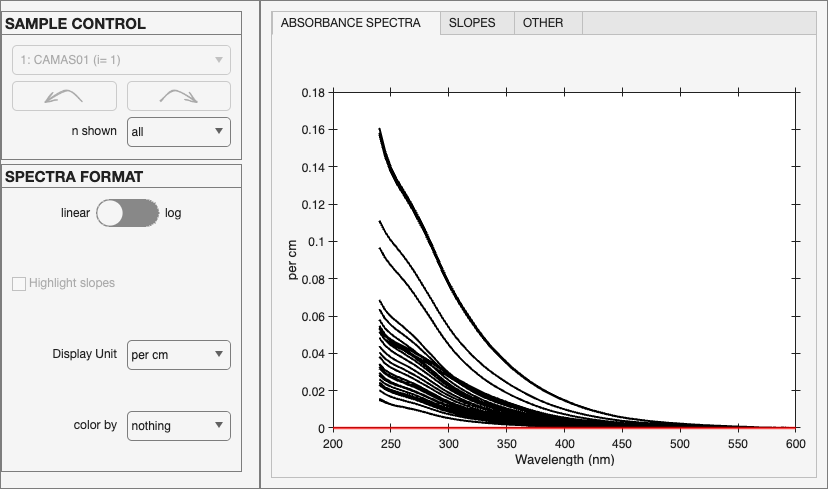

tbx.viewabsorbance(samples)

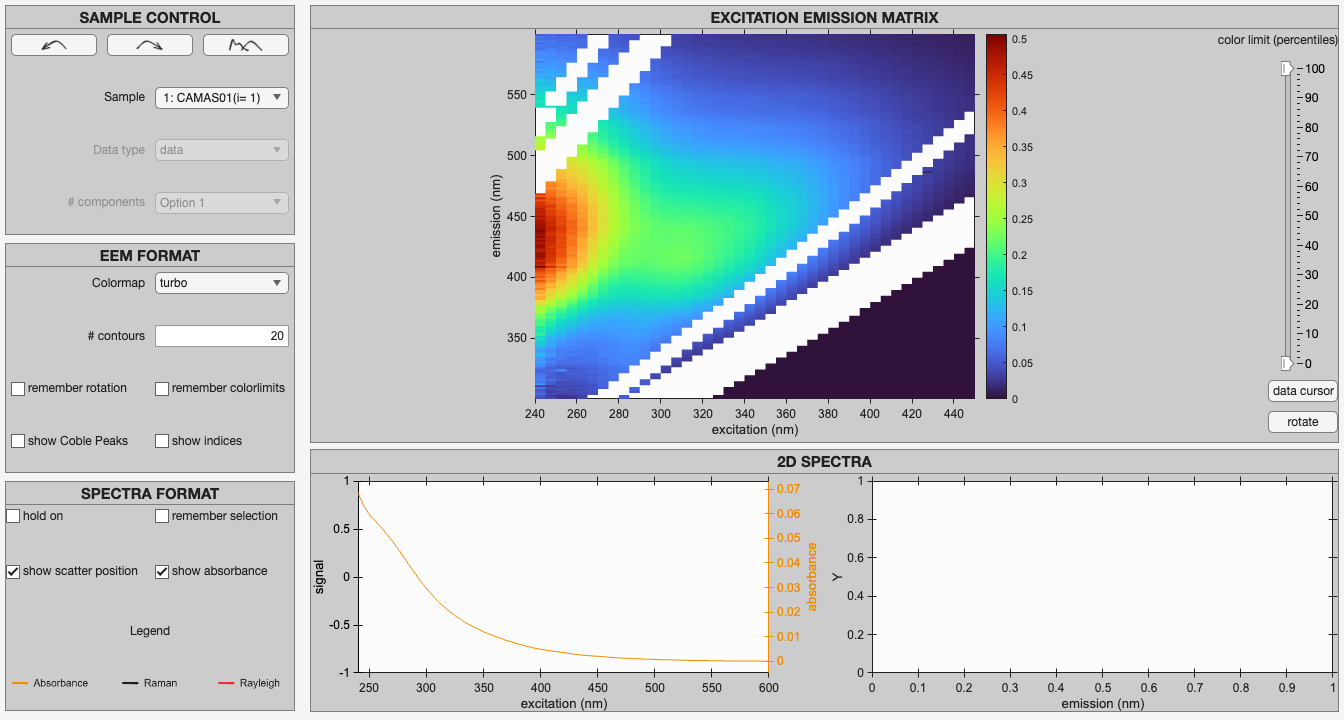

tbx.vieweems(samples)

You might notice some small issues with the data. Here, I picked an example of the 20th sample (identifier is `samples.i==24`). The entire excitation scan seems to be less intense than it's neighboring scans. `vieweems` can be used with the scan feature (sample control) to highlight the issue exactly:

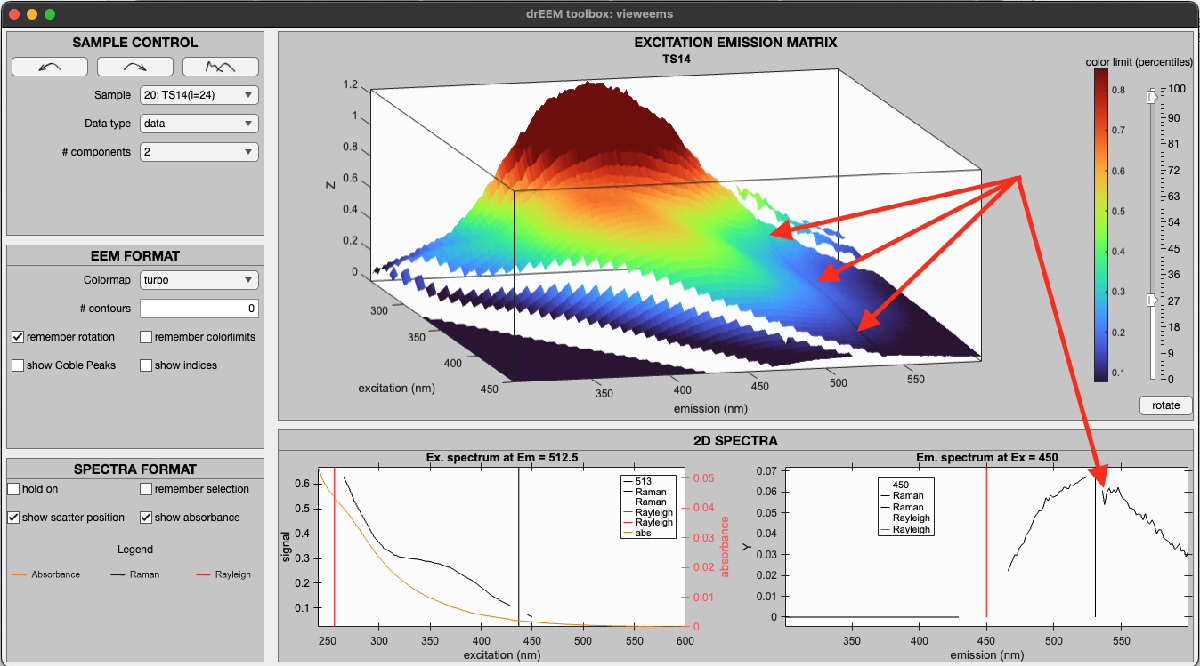

This is an job for `zapnoise`. Why? `zapnoise` can delete parts of an EEM in a specific sample only. We need to tell it which sample it should zap the data out of. You'll need to work with logical statements for the same and wavelengths for the emission and excitation wavelengths. Don't worry about needing to supply the exact wavelength, the function will find the closest match. For zapnoise, supplying an empty input means all excitation or emission wavelengths will be cut. Hence:

samples=tbx.zapnoise(samples,samples.i==24,537.6,[]);

And the result looks as follows:

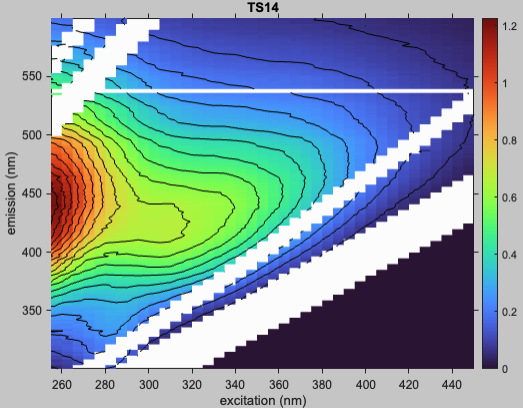

That looks a bit better. You could do this for all of the issues you notice, but I'll show some other functions. First, `spectralvariance`:

tbx.spectralvariance(samples)

In the EEM on the right, you'll notice that around the Rayleigh 2nd order scatter, there seems to be an aweful lot more variance than in the surrounding EEM. That suggests that some of the scatter is left over. Let's run `viewscatter` again:

tbx.viewscatter(samples)

Old options detected. These will be transfered to the GUI


This is an interactive tool, so I can't document the process here. But I have saved my more conservative choices in a variable for you to load and explore:

load("scatterSettings_refined2.mat")
samples=tbx.handlescatter(samples,scatteroptions)

samples =   drEEMdataset with properties:

            history: [17×1 drEEMhistory]
                  X: [32×182×40 double]
                abs: [32×73 double]
        suppSpectra: []
           filelist: {32×1 cell}
                  i: [32×1 double]
                 Ex: [40×1 double]
                 Em: [182×1 double]
                nEx: 40
                nEm: 182
            absWave: [73×1 double]
    suppSpectraAxis: [0×1 double]
            nSample: 32
             models: [0×1 drEEMmodel]
           metadata: [32×15 table]
    opticalMetadata: [0×0 table]
              split: [0×0 drEEMdataset]
             status: [1×1 drEEMstatus]
           userdata: []
     instrumentInfo: [0×0 struct]
    measurementInfo: [0×0 struct]


tbx.spectralvariance(samples)

After the repeated treatment, the variance around the 2nd order Rayleigh scatter is far less drastic. Perfect!

Now, it's time to show you a tool that was introduced in drEEM version 2. `rmspikes` estimates the noise level at every point in the EEM by deleting every in the EEM point once and interpolating with a 2D interpolation algorithm. It can thus account for naturally noisy parts (e.g. in the deep UV). The difference between the smooth interpolation and the real data can estimate the noise. `rmspikes` then deletes excessive noise, aka "spikes" data above a threshold (10x the noise estimate by default).

The issue is that every dataset requires an individual threshold factor. The option `details` is useful to explore whether excessive deletions are taking place. Then, once you find the setting you are happy with, the function can auto-zap excessive noise for you.

tbx.rmspikes(samples,thresholdFactor=15,details=true);

Diagnostic mode, no output will be assigned (no variable was specified).
2d-interpolation of alternatingly deleted data (4 rounds)...
Finishing up...


tbx.rmspikes(samples,thresholdFactor=20,details=true);

Diagnostic mode, no output will be assigned (no variable was specified).
2d-interpolation of alternatingly deleted data (4 rounds)...
Finishing up...


tbx.rmspikes(samples,thresholdFactor=30,details=true);

Diagnostic mode, no output will be assigned (no variable was specified).
2d-interpolation of alternatingly deleted data (4 rounds)...
Finishing up...


2d-interpolation of alternatingly deleted data (4 rounds)...
Finishing up...


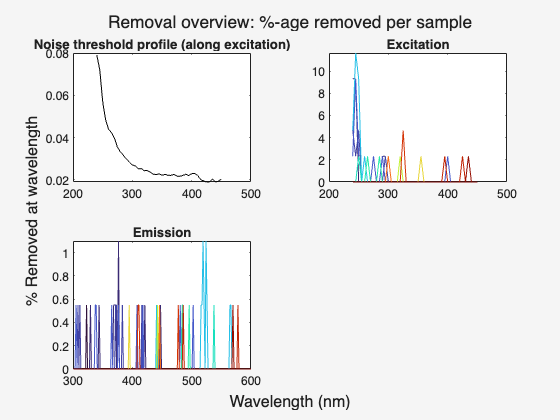

samples=tbx.rmspikes(samples,thresholdFactor=30);

Quite nice. But you might notice that it's not perfect. It's hard balance to land perfectly between too much deleting and too little. It's likely best to use the tool to remove the worst of the worst. The worst excessive noise it the type of data that might actually affect PARAFAC. So running conservative settings with `rmspikes` might just do the trick well enough.

Now, we can run spectralvariance once more.

tbx.spectralvariance(samples)

As you can see, the noise in the short excitation range is quite a lot higher than in the visible. This will be an issue for PARAFAC, especially if the samples are normalized to unit variance (`samples=tbx.scalesamples(samples,1);`). It's a good idea to exclude these wavelengths. For this we don't use `zapnoise`, but `subdataset`. It deletes spectral ranges for all samples, not just one.

samples=tbx.subdataset(samples,outEx=samples.Ex<255);

The final result of this looks quite nice:

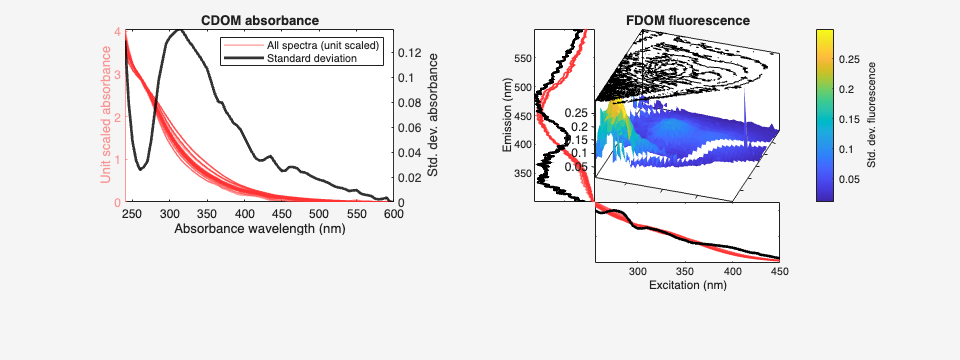

tbx.spectralvariance(samples)

As you can see from the dataset's history, we've done quite a bit and it's all documented. In your own datasets, you might end up spending a lot of time on this step as feeding good data into the PARAFAC algorithm is important if you want to get a well-fitting model out.

tbx.displayhistory(samples)

    #         Function                              User comment                                                                                                                                                                                                                                                                                              Function message                                                                                                                                                                                                                                                                     
    __    _________________    ______________________________________________________    ____________________________________________________________________________________________________________________________________________________________